### Parameters for analysis

clear

Parameters for spectral events data:

data_path = 'L:\Private\ch226126\Transient_Beta\data';
%data_path = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      %'EEG','Participant_Data','03_Processed_Data' );
task      = '02_Baseline';
band      = 'beta';
method    = 2;
chans     = [36 104]; % list of chans to plot
averaging = 'spec_events'; % averaging method
time_win  = [0 5000]; % time window to use relative to stim onset (ms)
num_cyc = "_7cycles"

num_cyc = "_7cycles"

beapp_tag = 'BL_TB_5sec';
srate = 250;

Group assignment information:

group_name     = {'TD','ASD','SPD','RTT','PMS','PHTS','TSC','SYN'};
groups_to_plot = [1,4:8];
grp_table      = fullfile(data_path,'Group_Assignments.mat');
for g = 1:length(groups_to_plot)
    grp_folder{g} = fullfile(data_path,group_name{groups_to_plot(g)});
end

Parameters for plotting:

conds_to_inc = 0; % if a subset, 0 to include all
seg_length   = abs(sum(time_win))/1000;
plot_var     = false;
save_fig     = false;
% equal_Ns     = false;
% by_cond      = false;
% fields to extract from spec_events structs
features{1,:} = {'eventnumber','maximapowerFOM','duration','Fspan'};
if seg_length > 0
    features{2,:} = {'Event rate (Hz)','Power (FOM)','Duration (ms)','F-span (Hz)'};
else
    features{2,:} = {'Events per segment','Power (FOM)','Duration (ms)','F-span (Hz)'};
end

 

### Load & process data

%% get information for plotting
colors = {'#4444c9','#32a852','#db4214','#a2142f','#77ac30','#edb120','#7e2f8e','#db4214'};
time_str = get_time_win_str(time_win);
chan_str = get_chan_str({},chans);
if isempty(chan_str), chan_str = '1020'; end
task_abbrevs = containers.Map({'02_Baseline','stepwise_loudness',  ...
                               'auditory_temporal_habituation', ...
                               'tactile_spatial_suppression',   ...
                               'tactile_temporal_habituation'}, ...
                               {'Resting state','SL','ATH','TSS','TTH'});
task_abb = task_abbrevs(task);

%% load group assignment table 
%load(grp_table,'groups')


%% load spectral events data
n_feats = length(features{1});
% load based on averaging method
switch averaging
    %% average eeg channels first, then run spectral events
    case 'eeg'
    load_chans = strrep(int2str(chans),' ','');
    if isempty(chans)
        load_chans = '1020';
    end
    % load channel SET data
    tag = [band '_' int2str(method) '_' load_chans beapp_tag];
    %load(fullfile(data_path,task,'spec_events',[tag '.mat']),'spec_events');
    load(fullfile(data_path,'spec_events',[tag '.mat']),'spec_events');
    % sort data by group
    sorted_eeg = sort_data_by_group_old(spec_events,groups,group_name);
    clear spec_events
    
    %% run spectral events on each channel, then average outputs
    case 'spec_events'
    if isempty(chans)
        chans = [22 9 33 24 124 122 36 104 58 62 96 70 83 45 108 52 92 11];
    end
    n_chans = length(chans);
    for i_g = 1:length(groups_to_plot)
        for i_c = 1:n_chans
            % load channel SET data
            tag = [band '_' int2str(method) '_' int2str(chans(i_c)) '_' beapp_tag,'_7cycles'];
           % load(fullfile(data_path,'spec_events',[tag '.mat']),'spec_events');
            load(fullfile(grp_folder{i_g},filesep,'spec_events',[tag '.mat']),'spec_events');
            % sort data by group
%             names = fieldnames(spec_events);
%                 for i_f = 1:size(names,1)
%                     re_names{i_f} = names{i_f}(1:9);
%                     n = names{i_f};
%                     spec_events = renameStructField(spec_events,n,re_names{i_f});
%                     clear n
%                 end
                
           % sorted_eeg(i_c) = sort_data_by_group_SET(spec_events,groups,group_name);
            sorted_eeg{i_g,i_c} = spec_events;
            clear spec_events
        end
    end
end
 sorted_eeg = cell2struct(sorted_eeg,group_name(groups_to_plot),1);
% get subject means and standard deviations
[data_mean,data_std] = subj_avg_spec_events(sorted_eeg,features{1},conds_to_inc);
% norm the event rate
if time_win(1) == 0
time_sec = time_win(2)/1000;
for i_g = 1:length(groups_to_plot)
    group = group_name{groups_to_plot(i_g)};
    for i_s = 1: length(data_mean.(group).eventnumber)
        data_mean.(group).eventnumber(i_s) = data_mean.(group).eventnumber(i_s) / time_sec ;
        data_std.(group).eventnumber(i_s) = data_std.(group).eventnumber(i_s) / time_sec;
    end %end individual
end %end group 
end

### Results

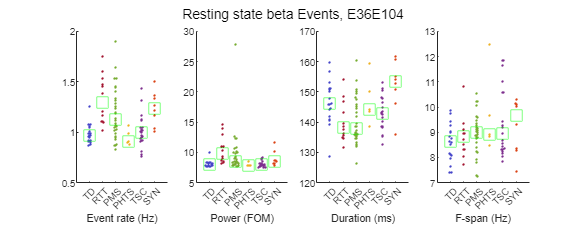

if plot_var
    plot_title = [task_abb ' ' band ' Event Std. Dev., ' chan_str];
else
    plot_title = [task_abb ' ' band ' Events, ' chan_str];
end

% iterate through features
f = figure('Position',[50 100 650 250]);
sgtitle((plot_title))
for i_f = 1:n_feats
    sp(i_f) = subplot(1,n_feats,i_f); hold on
    feat = features{1}{i_f};
    % iterate through groups
    eeg = cell(1,length(groups_to_plot)); group_label = eeg;
    for i_g = 1:length(groups_to_plot)
        group = group_name{groups_to_plot(i_g)};
        % create table from group average measure
        if plot_var
            group_eeg = struct2table(data_std.(group));
        else
            group_eeg = struct2table(data_mean.(group));
        end
        group_eeg.Properties.RowNames = group_eeg.id;
        % get group n
        n_subj = int2str(length(group_eeg.id));
        group_label{i_g} = group; %[group ', n=' n_subj];
        % add group eeg to cell with all groups
        eeg{i_g} = group_eeg.(feat);
        % add group stats to table
        grp_mu = mean(eeg{i_g}); grp_std = std(eeg{i_g});
        stats(i_f).([group '_N']) = n_subj;
        stats(i_f).([group '_mean_SD']) = sprintf('%.2f (%.2f)',grp_mu,grp_std);
    end

    %% plot distributions
    plotSpread( sp(i_f), eeg, 'xNames', group_label, 'showMM', 3,  ...
                'distributionColors', colors(groups_to_plot) );
    % style plot
    feat_label = features{2}{i_f}; 
    xlabel(feat_label)

    %% statistically compare groups
    if length(groups_to_plot) > 2
     %   [stats(i_f).p,~,~] = anova1(padcat(eeg{groups_to_plot}),[],'off');
    else
        [stats(i_f).p,~,~] = ranksum(eeg{1},eeg{2},'tail','left');
    end
end

% set(sp(1),'YLim',[0 2])
% set(sp(2),'YLim',[5 15])
% set(sp(3),'YLim',[110 180])
% set(sp(4),'YLim',[5 12])
% shrink legend and move off of plots
stat_table = struct2table(stats); 
stat_table.Properties.RowNames = features{2}; 
disp(stat_table)

                        TD_N        TD_mean_SD        RTT_N        RTT_mean_SD       PMS_N        PMS_mean_SD       PHTS_N      PHTS_mean_SD       TSC_N        TSC_mean_SD       SYN_N       SYN_mean_SD   
                       ______    _________________    ______    _________________    ______    _________________    ______    _________________    ______    _________________    _____    _________________

    Event rate (Hz)    {'18'}    {'0.99 (0.09)'  }    {'12'}    {'1.33 (0.24)'  }    {'30'}    {'1.19 (0.26)'  }    {'5'}     {'0.95 (0.08)'  }    {'21'}    {'1.01 


% save figure
if save_fig
    pause(0.2)
    fig_path = fullfile(data_path,'figures','spec_events');
    if ~exist(fig_path,'dir'), mkdir(fig_path); end
    if plot_var
        fig_fname = [band '_groups_' chan_str '_std'];
    else
        fig_fname = [band '_groups_' chan_str '_mean'];
    end
    fig_fname = fullfile(fig_path,fig_fname);
    saveas(f,fig_fname,'jpg')
end